clear;clc;clf;

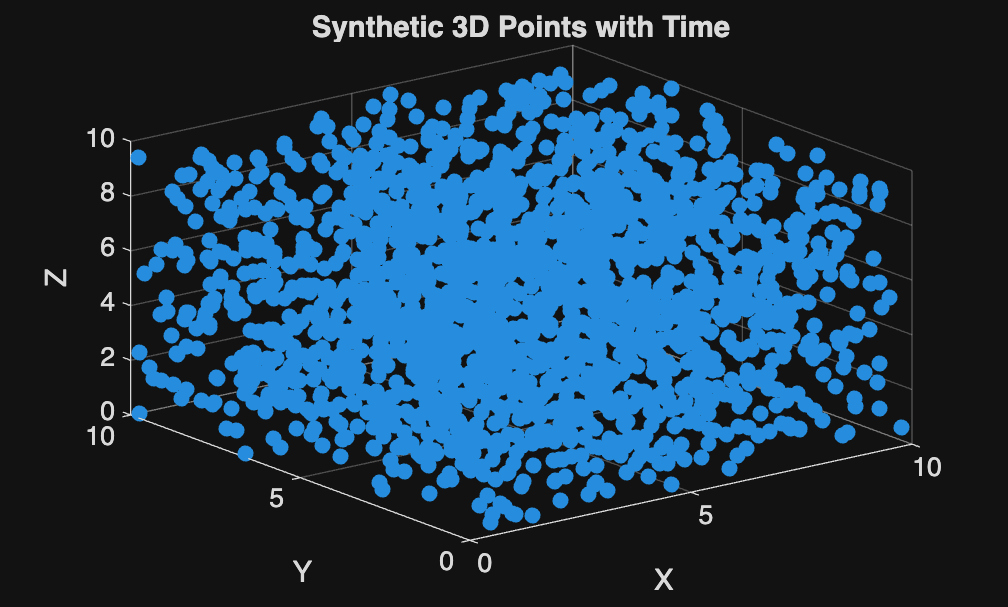

function points3D = generate3DPoints(numPoints, seed)
    rng(seed);
    points3D = 10 * rand(numPoints, 3); % Generate points in [0,10]^3
    time_values = (1:numPoints)'; % Assign unique time values
    points3D = [points3D, time_values]; % Append time values
end

numPoints = 2000; % Set number of points
seed = 23; % Set random seed
points3D = generate3DPoints(numPoints, seed);
figure;
scatter3(points3D(:,1), points3D(:,2), points3D(:,3), 'filled');
grid on; xlabel('X'); ylabel('Y'); zlabel('Z');
title('Synthetic 3D Points with Time');

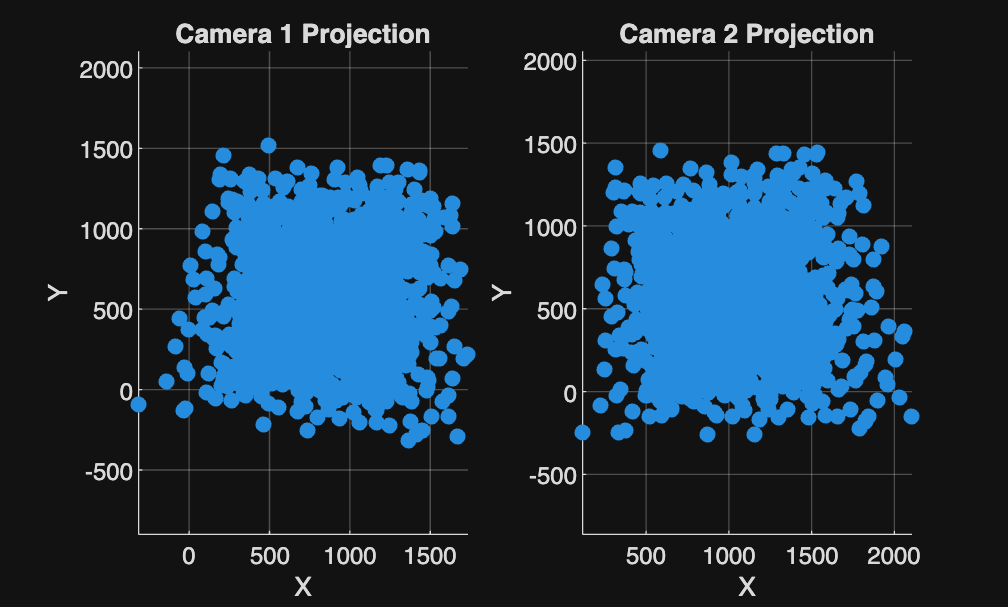

% Camera intrinsic matrix (assuming a simple pinhole model)
focal_length = 1000; % Arbitrary focal length
image_size = [1920, 1080]; % Image resolution (width x height)
K = [focal_length, 0, image_size(1)/2;
     0, focal_length, image_size(2)/2;
     0, 0, 1];
 
% Compute swarm center
swarm_center = mean(points3D(:,1:3), 1);

% Define two camera positions (extrinsics)
camera_distance = 10; % Distance from swarm center
camera_height = 3; % Camera Z height
camera_separation = 1.5; % Separation between cameras

% Compute camera positions along x-axis (assuming cameras are aligned along x-axis)
cam1_position = [swarm_center(1), swarm_center(2), 0] + [-camera_separation/2, -camera_distance, camera_height];
cam2_position = [swarm_center(1), swarm_center(2), 0] + [camera_separation/2, -camera_distance, camera_height];

% Compute rotations to face the swarm center
cam1_direction = swarm_center - cam1_position;
cam2_direction = swarm_center - cam2_position;

R1 = eye(3); % Placeholder rotation
R2 = eye(3); % Placeholder rotation

R1(:,3) = cam1_direction / norm(cam1_direction); % Forward vector
R2(:,3) = cam2_direction / norm(cam2_direction);
R1(:,1) = cross([0 0 1]', R1(:,3)); % Right vector
R2(:,1) = cross([0 0 1]', R2(:,3));
R1(:,2) = cross(R1(:,3), R1(:,1)); % Up vector
R2(:,2) = cross(R2(:,3), R2(:,1));

T1 = -R1 * cam1_position';
T2 = -R2 * cam2_position';

% Projection matrices
P1 = K * [R1, T1];
P2 = K * [R2, T2];

% TODO: Figure out a better way to project onto optical sensors that better
% represents how cameras actually work


% Project points onto both camera planes
points3D_hom = [points3D(:,1:3), ones(numPoints,1)];
proj1_hom = (P1 * points3D_hom')';
proj2_hom = (P2 * points3D_hom')';

% Normalize homogeneous coordinates
proj1 = [proj1_hom(:, 1:2) ./ proj1_hom(:, 3), points3D(:,4)];
proj2 = [proj2_hom(:, 1:2) ./ proj2_hom(:, 3), points3D(:,4)];

% Plot projections
figure;
subplot(1,2,1);
scatter(proj1(:,1), proj1(:,2), 'filled');
title('Camera 1 Projection');
xlabel('X'); ylabel('Y'); axis equal; grid on;

subplot(1,2,2);
scatter(proj2(:,1), proj2(:,2), 'filled');
title('Camera 2 Projection');
xlabel('X'); ylabel('Y'); axis equal; grid on;

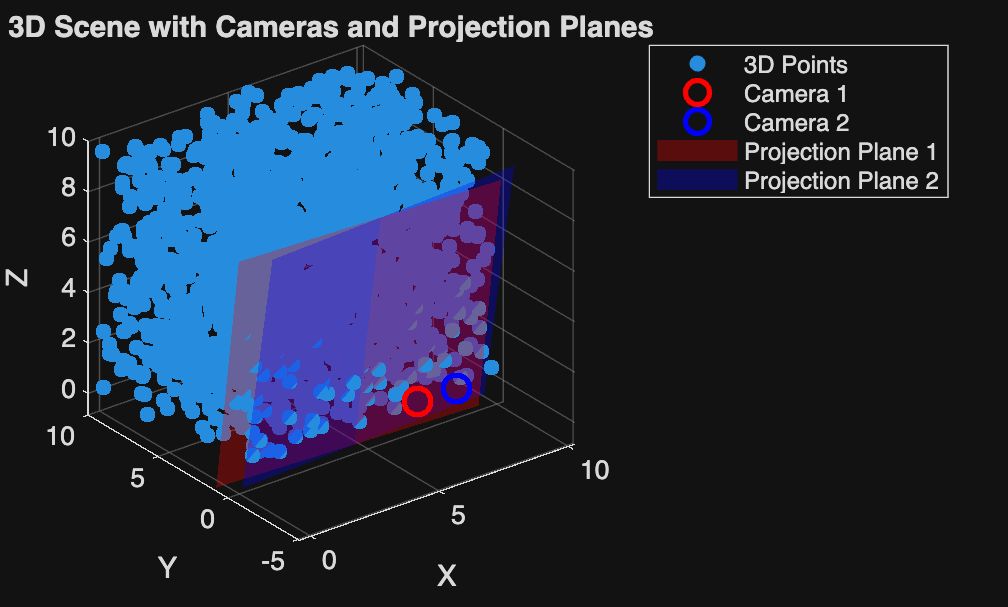

figure;
scatter3(points3D(:,1), points3D(:,2), points3D(:,3), 'filled');
hold on;
plot3(cam1_position(1), cam1_position(2), cam1_position(3), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
plot3(cam2_position(1), cam2_position(2), cam2_position(3), 'bo', 'MarkerSize', 10, 'LineWidth', 2);

% Define a projection plane in camera coordinate frame
[x_plane, y_plane] = meshgrid(linspace(-5, 5, 10), linspace(-5, 5, 10));
z_plane = ones(size(x_plane)) * 5;

% Transform projection planes into world coordinates
plane1_world = R1 * [x_plane(:)'; y_plane(:)'; z_plane(:)'] + cam1_position';
plane2_world = R2 * [x_plane(:)'; y_plane(:)'; z_plane(:)'] + cam2_position';

% Reshape for plotting
plane1_world = reshape(plane1_world', [10, 10, 3]);
plane2_world = reshape(plane2_world', [10, 10, 3]);

surf(plane1_world(:,:,1), plane1_world(:,:,2), plane1_world(:,:,3), 'FaceColor', 'red', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
surf(plane2_world(:,:,1), plane2_world(:,:,2), plane2_world(:,:,3), 'FaceColor', 'blue', 'FaceAlpha', 0.3, 'EdgeColor', 'none');

legend('3D Points', 'Camera 1', 'Camera 2', 'Projection Plane 1', 'Projection Plane 2');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on;
title('3D Scene with Cameras and Projection Planes');
hold off;

% Compute translation cross-product matrix
T_cross = [0, -T2(3), T2(2);
           T2(3), 0, -T2(1);
          -T2(2), T2(1), 0];

% Fundamental matrix: F = K^{-T} * T_cross * R * K^{-1}
F = inv(K)' * T_cross * R2 * inv(K);

% Validate epipolar constraint: cam2^T * F * cam1 = 0
proj1_h = [proj1(:,1:2), ones(numPoints,1)]';
proj2_h = [proj2(:,1:2), ones(numPoints,1)]';
errors = diag(proj2_h' * F * proj1_h);
mean_error = mean(abs(errors));
fprintf("Mean error of epipolar constraint in camera pixels is: %6.3f", mean_error)

Mean error of epipolar constraint in camera pixels is:  5.051

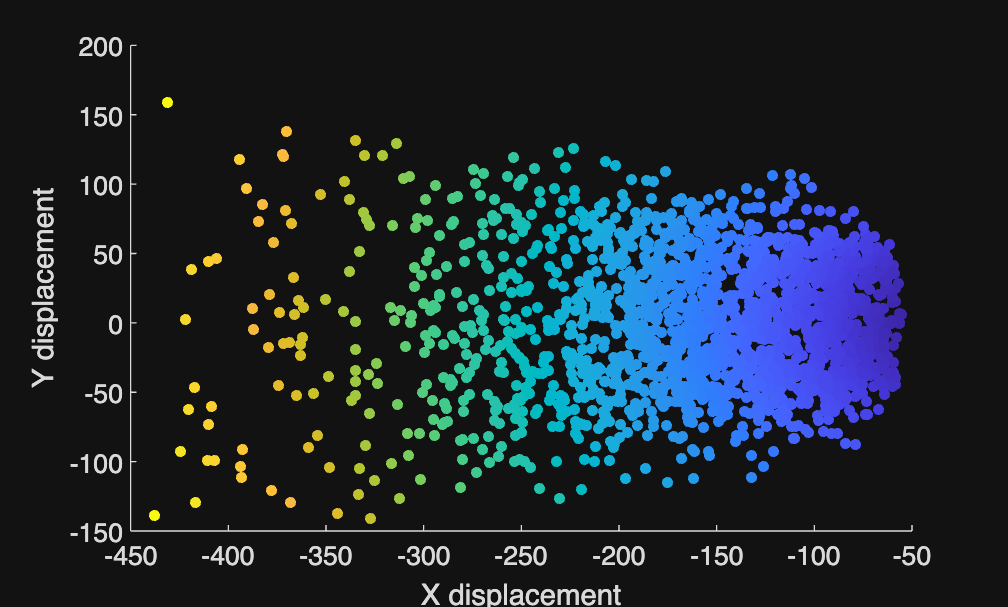

% Look at displacements from calibration points
v1 = 1:size(proj1,1);
v2 = 1:size(proj2,1);

variation = zeros(size(v1, 2), 2);

for n = 1:size(v1, 2)
    variation(n, 1) = proj1(v1(n), 1) - proj2(v2(n), 1);
    variation(n, 2) = proj1(v1(n), 2) - proj2(v2(n), 2);
end

figure()
scatter(variation(:,1), variation(:,2), 17, sqrt(variation(:,1).^2 + variation(:,2).^2), 'filled')
xlabel("X displacement")
ylabel("Y displacement")

% Test accuracy of F matrix estimation w/ synthetic data

addpath(genpath("/Users/nbonnie/Desktop/3D_reconstruction_sandbox/calfree_scripts"))

calTraj.j1 = proj1;
calTraj.j2 = proj2;

disp('Estimating fundamental matrix; this may take a while (up to ~1hr)... '+ string(datetime('now')))

Estimating fundamental matrix; this may take a while (up to ~1hr)... 09-Feb-2025 00:05:36


stereoParams = estimate360CameraParameters(calTraj.j1, calTraj.j2,'Norm8Point');
disp('Calibration complete: '+ string(datetime('now')))

Calibration complete: 09-Feb-2025 00:05:36


errors_exp = diag(proj2_h' * stereoParams.F * proj1_h);
mean_error_exp = mean(abs(errors_exp));
fprintf("Mean error of epipolar constraint in camera pixels is: %6.3f", mean_error_exp)

Mean error of epipolar constraint in camera pixels is: 109.526

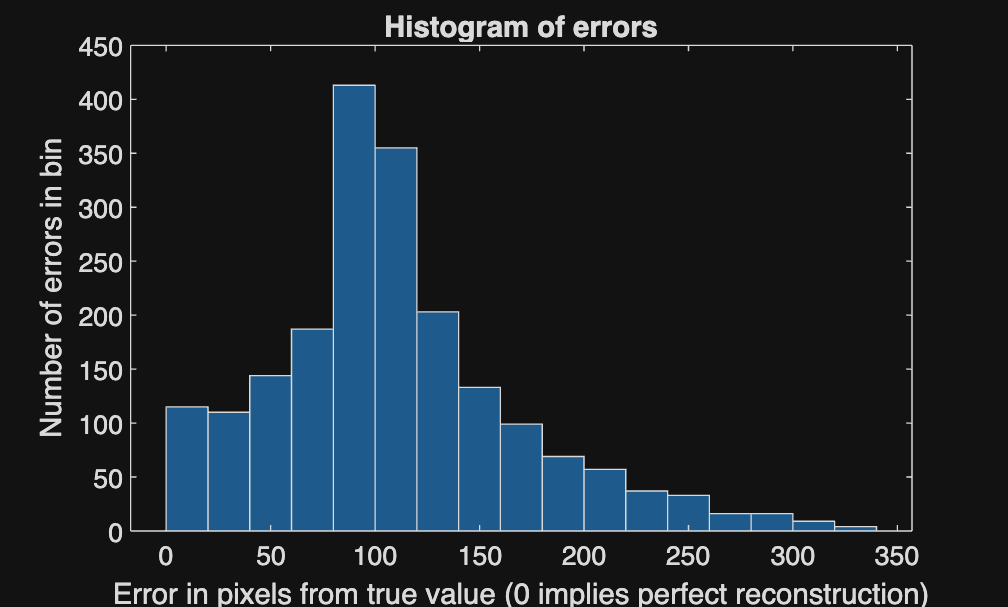

figure;
histogram(abs(errors_exp))
ylabel("Number of errors in bin")
xlabel("Error in pixels from true value (0 implies perfect reconstruction)")
title("Histogram of errors")